# Solutions to Exercises on Constrained Polynomial Approximation (2D) (17.12.2024): Part I

Course: Data Science for Engineers II

Author: Dimitar Ninevski

Date: 30.12.2024

## Prepare workspace

close all;
clear;

## Question 1

### Part a.

We have to load the dataset and determine a row where there is active pressure on some of the cells.

allData = readmatrix('T3v0_D.csv');

Same procedure as in the live script from the lecture. Each row contains 30 sensor values, which later need to be converted into a $6 \times 5$ matrix. First, we determine the maxima of the data columnwise. 

[maxVal, idx] = max(allData);

The maxVal variable contains the maxima for each column. 

We can plot it, to see that several columns have some high values. This is to be expected, since there are several sensors where something is happening. 

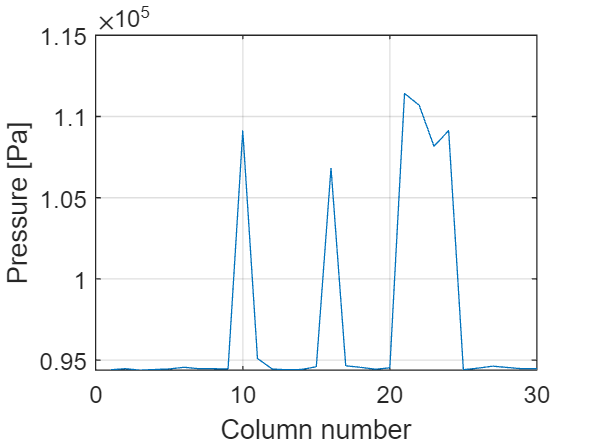

figure;
plot(maxVal);
grid on;
xlabel('Column number');
ylabel('Pressure [Pa]');

We can still find the highest peak on the graph, which will give us the column (sensor) where there is maximal pressure.

[~, colMax] = max(maxVal);

On the other hand, the variable idx from line 4 contains the indices of the maxima in each column. So it tells us, in which **row **is the maximum in that particular column.

rowMax = idx(colMax);

According to these calculations, the maximum element in the matrix is in the 2508th row, so that is the one we will take a closer look at.

#### Extract data

The second row in the matrix contains the value from the sensors with no external pressure (other than the atmospheric pressure). We can use these as a baseline to subtract, so that our values are "zeroed" and we don't have to deal with large numbers. 

rowData = allData(rowMax, :) - allData(2, :);
rowData = rowData./max(max(rowData));

Next, we will convert the data from a row to a $6 \times 5$ matrix corresponding to the grid.

nrSensorHor = 5;
nrSensorVer = 6;
sensorData = reshape(rowData, nrSensorVer, nrSensorHor);

We can now visualize the raw sensor data from that row to see if it looks like what we expect it to,

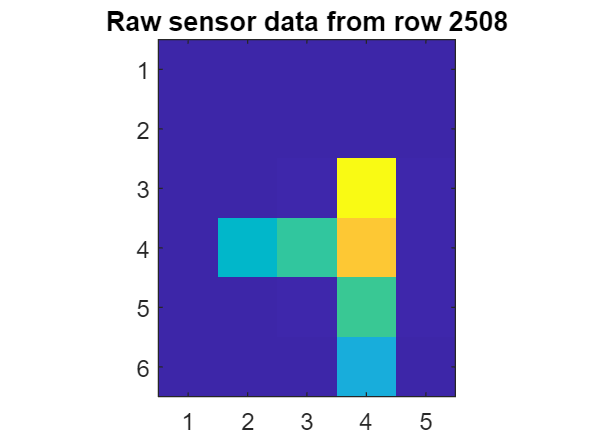

figure
imagesc(sensorData);
axis image;
title(['Raw sensor data from row ', num2str(rowMax)]);

We can see that the raw data looks like what we expect, so we have done things correctly until now.

#### Perform unconstrained polynomial interpolation

First we need to define the degrees of the polynomials and the appropriate Vanermonde matrices.

degX = size(sensorData, 2) - 1;
degY = size(sensorData, 1) - 1;
x = linspace(-1, 1, degX + 1);
y = linspace(-1, 1, degY + 1);

Now we can define the Vandermonde matrices

Vx = vander(x);
Vy = vander(y);

Perform unconstrained polynomial interpolation

uncCoeffs = pinv(Vy)*sensorData*pinv(Vx');

#### Visualize the unconstrained interpolation

Because we have more sensors vertically than horizontally, I will accordingly define an appropriate number of points for visualization in both directions.

factor = 20;
xPlot = linspace(-1, 1, factor*nrSensorHor);
yPlot = linspace(-1, 1, factor*nrSensorVer);
Vxb = vander(xPlot);
Vyb = vander(yPlot);
VxPlot = Vxb(:, end-degX:end);
VyPlot = Vyb(:, end-degY:end);

Compute the interpolating surface

interpSurface = VyPlot*uncCoeffs*VxPlot';

In order to visualize the interpolating surface, we will use the *imagesc* function, as well as the *surf* function.

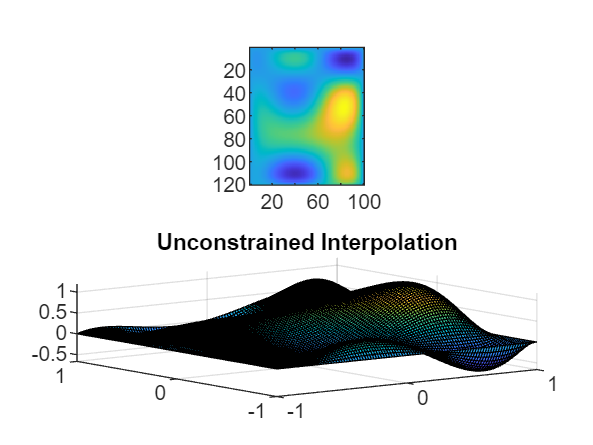

figure
subplot(2,1,1)
imagesc(interpSurface);
axis image;
subplot(2,1,2)
[xSurf, ySurf] = meshgrid(xPlot, yPlot);
surf(xSurf, ySurf, interpSurface);
title('Unconstrained Interpolation');

As we can see, due to the Runge phenomenon, the results don't look too appealing.

### Part b.

Based on the raw data, I will define that the value and derivatives need to be zero at the four corners. Let's see if that makes it a bit better.

First, let's define the value constraint matrices.

vCx = Vx([1 end], :);
vCy = Vy([1 end], :);

Next, let's define the derivatives of the Vandermonde matrices.

Dx = diag(degX:-1:1, -1);
Dy = diag(degY:-1:1, -1);
dVx = Vx*Dx;
dVy = Vy*Dy;

Now, we can also define the derivative constraint matrices.

dCx = dVx([1 end], :);
dCy = dVy([1 end], :);

Finally, the computation can be performed as

Cx = [vCx; dCx];
Cy = [vCy; dCy];
kronP = kron(Cx, Cy);
N = null(kronP);
vecCoeffsDer = N*pinv(kron(Vx, Vy)*N)*sensorData(:);
valConCoeffs = reshape(vecCoeffsDer, degY + 1, degX + 1);

#### Plot the constrained polynomial surface

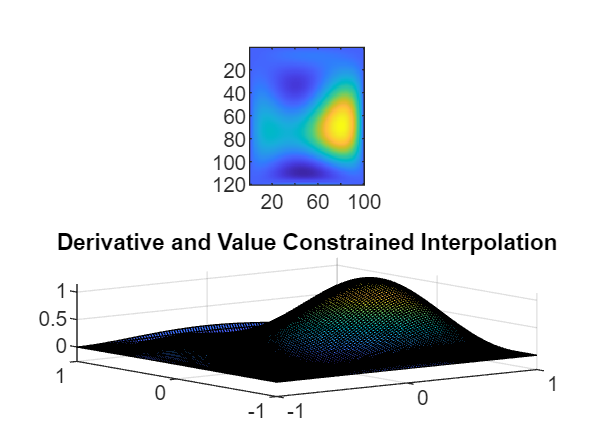

interpSurfaceDVC = VyPlot*valConCoeffs*VxPlot';
figure
subplot(2,1,1)
imagesc(interpSurfaceDVC);
axis image;
subplot(2,1,2)
surf(xSurf, ySurf, interpSurfaceDVC);
title('Derivative and Value Constrained Interpolation');

#### Discussion

The constraints improve the Runge phenomenon, but hide the shape of the data and don't really display the T structure of the object. This is not ideal. I tried different constraints, by taking the first and last columns or rows to be zero etc, but the results were either really similar to the original one, or completely ignored the structure of the data. These attempts aren't here, but I encourage you to try them out and see how it works.

### Part c.

We need to refine our grid of points, from a $6 \times 5$ into an $11 \times 9$ grid, by adding the middle values between the sensors.

First, let's define all middle points horizontally and then vertically separately.

middlePtsX = (sensorData(:,1:end-1) + sensorData(:,2:end))/2;
middlePtsY = (sensorData(1:end-1,:) + sensorData(2:end,:))/2;

Next, we can define a placeholder for the new refined grid.

newLengthX = size(sensorData, 2) + size(middlePtsX, 2);
newLengthY = size(sensorData, 1) + size(middlePtsY, 1);
newData = zeros(newLengthY, newLengthX);

We can fill in this placeholder with the old sensor data, as well as with the computed middle points.

newData(1:2:newLengthY, 1:2:newLengthX) = sensorData;
newData(2:2:newLengthY, 1:2:newLengthX) = middlePtsY;
newData(1:2:newLengthY, 2:2:newLengthX) = middlePtsX

newData =     0.0014    0.0012    0.0010    0.0012    0.0014    0.0011    0.0007    0.0009    0.0010
    0.0015         0    0.0011         0    0.0012         0    0.0023         0    0.0014
    0.0017    0.0015    0.0013    0.0011    0.0010    0.0024    0.0038    0.0029    0.0019
    0.0014         0    0.0017         0    0.0033         0    0.5019         0    0.0048
    0.0012    0.0017    0.0022    0.0039    0.0056    0.5028    1.0000    0.5038    0.0076
    0.0025         0    0.2307         0    0.2807         0    0.9342         0    0.0068
    0.0038    0.2316    0.4593    0.5075    0.5558    0.7121    0.8684    0.4372    0.0060
    0.0033         0    0.2314         0    0.2814         0    0.7226         0    0.0056
    0.0027    0.0031    0.0034    0.0052    0.0069    0.2918    0.5767    0.2909    0.0052
    0.0030         0    0.0028         0    0.0056         0    0.4937         0    0.0046


So far we have computed the middle points horizontally and vertically, but we need to go diagonally also. In other words, we also need to compute the middle of the middle points (the locations of these are marked by zeros in the matrix newData).

middleOfMiddle = (middlePtsX(1:end-1,:) + middlePtsX(2:end,:))/2;
%middleOfMiddleY = (middlePtsY(:,1:end-1) + middlePtsY(:,2:end))/2
% ^This is the same as middleOfMiddle^.

newData(2:2:newLengthY, 2:2:newLengthX) = middleOfMiddle;

#### Plot the raw data as well as the "refined" data

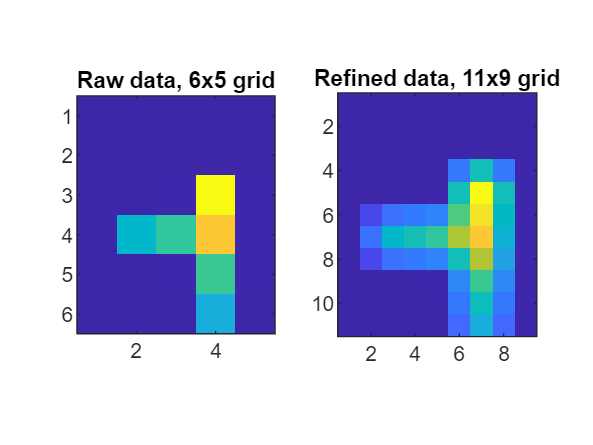

figure;
subplot(1,2,1)
imagesc(sensorData);
axis image;
title('Raw data, 6x5 grid');
subplot(1,2,2);
imagesc(newData);
axis image;
title('Refined data, 11x9 grid');

The refined grid increases the number of points we have, which in turn increases the degrees of the polynomials we can use. Let's see how this affects our surface fitting attempts.

### Part d.

We will use the same code as from parts a and b, just with different polynomial degrees. I will also add the letter "r" before every name, to distinguish between this new code and the version from above.

#### Unconstrained surface fitting

rdegX = size(newData, 2) - 1;
rdegY = size(newData, 1) - 1;
rx = linspace(-1, 1, rdegX + 1);
ry = linspace(-1, 1, rdegY + 1);

Now we can define the Vandermonde matrices. 

rVx = vander(rx);
rVy = vander(ry);

Perform unconstrained polynomial interpolation

runcCoeffs = pinv(rVy)*newData*pinv(rVx');

#### Constrained surface fitting

We will first compute all the coefficients, and then visualize everything in one go.

First, let's define the value constraint matrices.

rvCx = rVx([1 end], :);
rvCy = rVy([1 end], :);

Next, let's define the derivatives of the Vandermonde matrices.

rDx = diag(rdegX:-1:1, -1);
rDy = diag(rdegY:-1:1, -1);
rdVx = rVx*rDx;
rdVy = rVy*rDy;

Now, we can also define the derivative constraint matrices.

rdCx = rdVx([1 end], :);
rdCy = rdVy([1 end], :);

Finally, the computation can be performed as

rCx = [rvCx; rdCx];
rCy = [rvCy; rdCy];
rkronP = kron(rCx, rCy);
rN = null(rkronP);
rvecCoeffsDer = rN*pinv(kron(rVx, rVy)*rN)*newData(:);
rvalConCoeffs = reshape(rvecCoeffsDer, rdegY + 1, rdegX + 1);

#### Plot the results 

We can use the same xPlot and yPlot as above. But we need to compute the new Vandermonde matrices, cause of the new degrees.

rVxPlot = Vxb(:, end-rdegX:end);
rVyPlot = Vyb(:, end-rdegY:end);
rinterpSurface = rVyPlot*runcCoeffs*rVxPlot';
rinterpSurfaceDVC = rVyPlot*rvalConCoeffs*rVxPlot';

Now we can plot

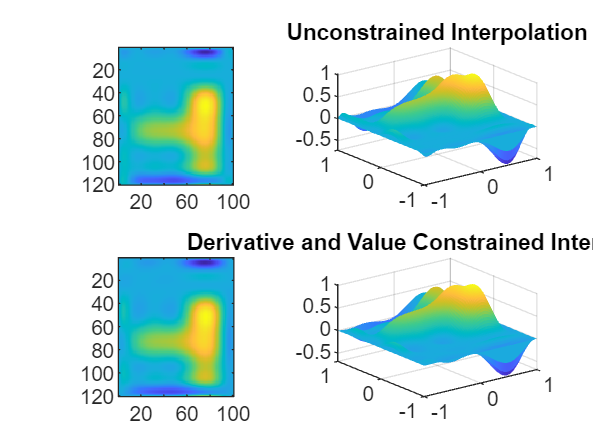

figure
subplot(2,2,1)
imagesc(rinterpSurface);
axis image;
subplot(2,2,2)
surf(xSurf, ySurf, rinterpSurface, 'EdgeColor','none');
title('Unconstrained Interpolation');
subplot(2,2,3)
imagesc(rinterpSurfaceDVC);
axis image;
subplot(2,2,4)
surf(xSurf, ySurf, rinterpSurfaceDVC, 'EdgeColor','none');
title('Derivative and Value Constrained Interpolation');

Discussion: We can see that just refining the grid already drastically improves the results. The constraints we defined aren't changing much (although they are changing a bit). Now we could go back and change the constraints, to further improve the result. This is something you can try and change on your own if you so wish. The changes would need to happen in lines 95, 96 (for the value constraints) as well as 101, 102 (for the derivative constraints).